clear; close all;

% Load data
load("2_data\test_references_single_pendulum_v1.mat");

% Setup MRT-MOLE
mrt_mole = CMRTMOLE(@run_single_pendulum_feedforward_dynamics, 1, 2, [1, 0], 3);

% Number trials per reference
J = 5; 

% Run MRT-MOLE
tic; 
emat = mrt_mole.run_mrt_mole(rc, J, uc);
toc;

Elapsed time is 4.824312 seconds.


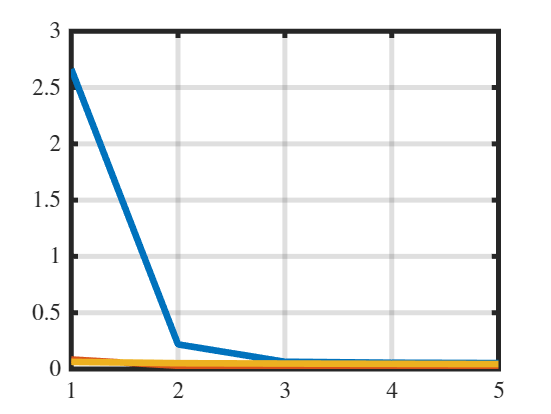


figure;
plot(emat(:, 1)); hold on;
plot(emat(:, 2));
plot(emat(:, 3));